Loading simulation Model,

simulationModel = "run_q2_test";

Running the experiment

load("system_parameters.mat");
Ts = 0.001;
T_sample = Ts;
load("feed_limited_displacement.mat")
ts = dispProfile(:,1);
xs = dispProfile(:,2);

startTime = 0;
endTime = ts(end);

load("system_parameters.mat");
xd = timeseries(xs,ts);
mkdir("../PID_tracking_test");
load("pid_parameters.mat");

Kp = pid_param.Kp;
Ki = pid_param.Ki;
Kd = pid_param.Kd;
ad = exp(-Ts*pid_param.a);
ad

ad = 0.9255


% -- Run the simulink model programatically

set_param(simulationModel,"StartTime",string(startTime));
set_param(simulationModel,"StopTime",string(endTime));
set_param(simulationModel,"SimulationCommand","start");

pause(endTime + 5);

out = struct();
out.x_resp = x_res;
out.xd_in = x_sim_in;
out.u_in = c_in;

save("Q2_PID_tracking_experiment_data.mat","out");

## Plotting figures

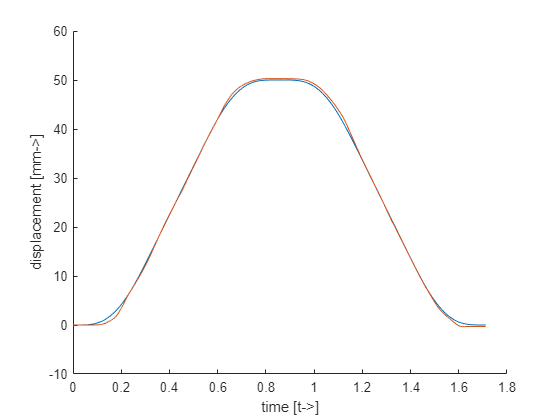

figure();
hold on;
plot(x_sim_in.time,x_sim_in.signals.values);
plot(x_res.time,x_res.signals.values);

xlabel("time [t->]")
ylabel("displacement [mm->]")
hold off;

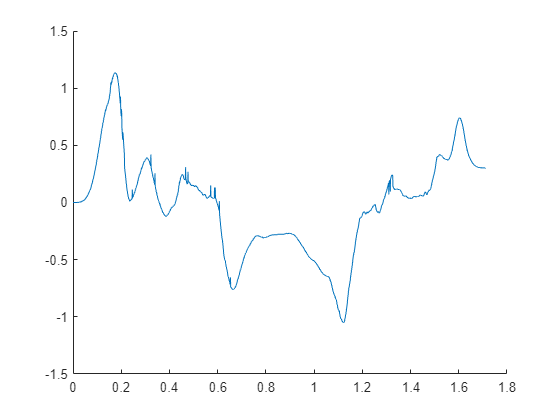


figure();
hold on;
err = x_sim_in.signals.values - x_res.signals.values;
plot(x_sim_in.time,err)


rms(err)

ans = 0.4272